UNIVERSIDAD INDUSTRIAL DE SANTANDER, COLOMBIA

NUMERICAL ANALYSIS

JORGE LUIS BACCA

# *Laboratory 5: Newton-Raphson and Secant Method*

## **Instructions:**

- Send the **.mlx** and **.m** files including the solution to each point of the practice with name ***Lab5_name_lastname.zip****.*

- Send the report and all created files in a rar or *zip* file with name ***Lab5_name_lastname.rar*** and subject **Analisis_Lab5_name** to **jbacquin@uis.edu.co.**

- You are allowed to use internet, notes, and .m files that you have created before.

## **Purposes:**

- To implement the Newton-Raphson method in Matlab.

- To implement the Secant method in Matlab.

## Guide functions:

You will be introduced to some functions that may be useful for the development of this laboratory. You **DO NOT **have to use them if you do not requier them. This is with the purpose of providing a guide for you to understand Matlab and start coding more eficciently.

**Note:** Remember to save your Matlab functions as '.m' files.

- If an array X already exists, you can use it to increase the size of the array and append other elements to the array. For example, **X(end+1) = 5** increases the length of X by 1 and adds a new element to the end of X.

- **diff:** Use the diff function to approximate partial derivatives with the syntax **Y = diff(f)**, where f is a vector of function values evaluated on some domain, X.

- **Plot:** **plot(X,Y)** creates a 2D line plot of the data in Y versus the corresponding values in X.

You can change the color or style of lines or add markers by including an optional line specification when calling the plot function. For example:

':' represents a dotted line.

'g:' represents a green dotted line.

'g:*' represents a green dotted line with star markers.

'*' represents star markers without a line.

- **hold on:** hold on sets the axis hold state to on, which preserves the current axis graphs so that new graphs added to the axes do not override existing graphs.

- **hold off:** hold off sets the hold state of the axes to off so that new graphs added to the axes will clear existing graphs and reset all axis properties.

## **Implementing **

- (1.0 points) Create a Matlab function called *my_newton_function_name_lastname()* to find the root of a function using the Newton-Raphson method. The arguments of the function must be: the function to be evaluated $f\left(x\right)$ (as an inline function), the initial point [$p_0$], the derivate of the function $f^{\prime } \left(x\right)$ (as an inline function), and the stopping criteria (the number of iterations or the error). Find the three roots of the function $f\left(x\right)=x^3 +13x^2 -297\ldotp 5x+0\ldotp 00000375e^x$. You have to choose a proper initial point for each root.  

                Include the prints:

                - $k:\textrm{Number}\;\textrm{of}\;\textrm{current}\;\textrm{iteration}$

                - $p_k :\textrm{Value}\;\textrm{of}\;\textrm{the}\;\textrm{root}\;\textrm{at}\;\textrm{iteration}\;k$

                - $f\left(p_k \right):\textrm{Value}\;\textrm{of}\;\textrm{the}\;\textrm{function}\;\textrm{evaluated}\;\textrm{in}\;p_k$

                -$f^{\prime } \left(p_k \right):\textrm{Value}\;\textrm{of}\;\textrm{the}\;\textrm{derivative}\;\textrm{evaluated}\;\textrm{in}\;p_k$

                -$\frac{|p_k -p_{k-1} |}{|p_k |}:\textrm{Relatvie}\;\textrm{error}$

syms x
fun = @(x) x.^3 + 13.*x.^2 - 297.5.*x + 0.00000375.*exp(x);
der = matlabFunction(diff(fun,x));
Iter=10;
error = 1e-5;
roots = zeros(3, 1);
for i = 1:3
    switch i
        case 1
            p0 = -20;
        case 2
            p0 = 5;
        case 3
            p0 = 10;
    end

    fprintf('%d', i);
    root=my_newton_function_Juan_Jaimes(fun,p0,der,Iter,error)
    roots(i) = root;
end

1

k   xk                             f(xk)                         f'(xk)                       |xk - xk-1|
         1 -28.235294                     3150.000000                    382.500000                     8.235294                      
         2 -25.480995                     -3746.061470                   1360.077855                    2.754299                      
         3 -24.951476                     -523.078057                    987.837427                     0.529518                      
         4 -24.932333                     -17.640288                     921.490145                     0.019143                      
         5 -24.932309                     -0.022660                      919.123059                     0.000025                      
         6 -24.932309                     -0.000000                      919.120012                     0.000000                      
Raiz encontrada.



root = -24.9323

2

k   xk                             f(xk)                         f'(xk)                       |xk - xk-1|
         1 -6.216278                      -1037.499443                   -92.499443                     11.216278                     
         2 -0.063891                      2111.479943                    -343.196895                    6.152386                      
         3 -0.000176                      19.060438                      -299.148921                    0.063716                      
         4 0.000000                       0.052256                       -297.504563                    0.000176                      
         5 0.000000                       0.000000                       -297.499996                    0.000000                      
Raiz encontrada.



root = 1.2605e-08

3

k   xk                             f(xk)                         f'(xk)                       |xk - xk-1|
         1 12.570305                      -674.917401                    262.582599                     2.570305                      
         2 11.971938                      301.843435                     504.445203                     0.598367                      
         3 11.931199                      18.102315                      444.345726                     0.040739                      
         4 11.931013                      0.081603                       440.341427                     0.000185                      
         5 11.931013                      0.000002                       440.323237                     0.000000                      
Raiz encontrada.



root = 11.9310

fprintf('\nRaices encontradas:\n');


Raices encontradas:


disp(roots);

  -24.9323
    0.0000
   11.9310



- (0.5 points) Create a Matlab function called *my_visual_newton_function_name_lastname()* to visualize the behaviour of the Newton method. The arguments of the function must be: the function to be evaluated $f\left(x\right)\;$(as an inline function), the initial point [$p_0$], the derivate of the function, $\textrm{fp}\left(x\right)$, and the number of iterations. Make a script called *run_2b_name_lastname.m* in which you use the created function to visualize the behavior of the Newton method when solving the exercise in 3 and conclude about the convergence of the method. For instance, 

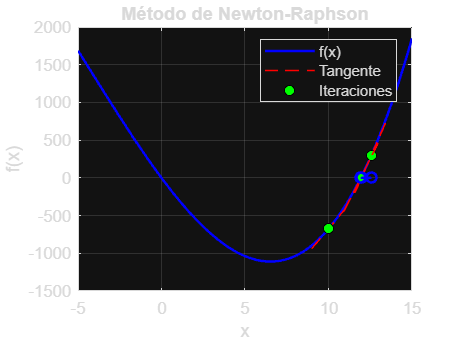

syms x
fun = @(x) x.^3 + 13.*x.^2 - 297.5.*x + 0.00000375.*exp(x);
der = matlabFunction(diff(fun,x));
Iter=5;
error = 1e-3;
my_visual_newton_function_Juan_Jaimes(fun,p0,der,Iter);

- (1.0 points) Create a Matlab function called *my_Secant_function_name_lastname()* to find the root of a function using the Secant method. The arguments of the function must be: the function to be evaluated $f\left(x\right)$ (as an inline function), and two  initial points [$p_{0,} p_1$], and the stopping criteria (the number of iterations or the error). Find a root of the function $f\left(x\right)=x^3 +-3x+2$, starting form $p_{0\;} =-2\ldotp 6\;\textrm{and}\;p_1 =-2\ldotp 4$ 

fun = @(x) x.^3 - 3.*x +2;
Iter=5;
error = 1e-3;
p0= -2.6;
p1 = -2.4;
root=my_secant_function_Juan_Jaimes(fun,p0,p1,Iter)

root = -2.1066

(1.0 points) Create a Matlab function called *my_visual_Secant_function_name_lastname()* to find the root of a function using the Secant method.

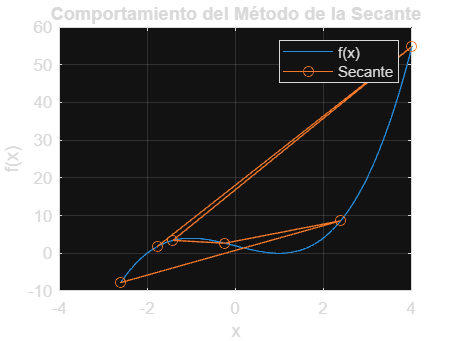

fun = @(x) x.^3 - 3.*x +2;
Iter=5;
error = 0;
my_visual_secant_function_Juan_Jaimes(fun,p0,-p1,Iter);

## **multiple root**

(1.0) Use the Newton-Raphson method for the following equation $f\left(x\right)=x^3 -3x+2=0$ to find the roots 

(a) r = -2  starting from p_0 = -2.4

(b) r = 1  starting from  p_0 = 1.2

fun = @(x) x.^3 - 3.*x +2;
Iter=5;der = matlabFunction(diff(fun,x));
Iter=10;
error = 1e-5;
roots = zeros(2, 1);
for i = 1:2
    switch i
        case 1
            p0 = -2.4;
        case 2
            p0 = 1.2;
    end

    fprintf('%6d', i);
    root=my_newton_function_Juan_Jaimes(fun,p0,der,Iter,error)
    roots(i) = root;
end

     1

k   xk                             f(xk)                         f'(xk)                       |xk - xk-1|
         1 -2.076190                      -4.624000                      14.280000                      0.323810                      
         2 -2.003596                      -0.720987                      9.931701                       0.072594                      
         3 -2.000009                      -0.032442                      9.043191                       0.003587                      
         4 -2.000000                      -0.000077                      9.000103                       0.000009                      
Raiz encontrada.



root = -2.0000

     2

k   xk                             f(xk)                         f'(xk)                       |xk - xk-1|
         1 1.103030                       0.128000                       1.320000                       0.096970                      
         2 1.052356                       0.032939                       0.650028                       0.050674                      
         3 1.026401                       0.008367                       0.322362                       0.025956                      
         4 1.013258                       0.002109                       0.160496                       0.013143                      
         5 1.006643                       0.000530                       0.080074                       0.006614                      
         6 1.003325                       0.000133                       0.039993                       0.003318                      
         7 1.001664                       0.000033                       0.019985   

root = 1.0002

fprintf('\nRaices encontradas:\n');


Raices encontradas:


disp(roots);

   -2.0000
    1.0002



Please conclude the results by asking which root is the fastest and why?

***Rta:*** (Write your answer here! )

La raiz más rápida en este caso es la primera, en la que usamos punto inicial negativo. Aunque a simple vista el segundo punto inicial parece estar más cerca de la raíz la curva de la función ayuda a que en menos iteraciones converja.